# Waste Analysis Demo

Use the `ThermoeconomicModel` function to perform a waste analysis

### **Create the Thermoeconomic Model**

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
model=ThermoeconomicModel(file,'DiagnosisMethod','NONE','Debug',false);

### Show the results for the reference state

Show the direct unit cost table values

showResults(model,'dfcost');


Flows Exergy Cost - REF

Key         B(MW)      B*(MW)    Bin*(MW)     Br*(MW)      k*(J/J)    kin*(J/J)     kr*(J/J)
—————————————————————————————————————————————————————————————————————————————————————————————
NG         72.465      72.465      72.465       0.000       1.0000       1.0000       0.0000
B1          0.000       0.000       0.000       0.000       0.0000       0.0000       0.0000
B2         28.651      53.837      51.022       2.814       1.8790       1.7808       0.0982
B3         50.339      93.719      88.815       4.903       1.8618       1.7643       0.0974
B4        102.530     168.868     161.280       7.588       1.6470       1.5730       0.0740
B5         38.810      63.920      61.048       2.872       1.6470       1.5730       0.0740
B6         14.784      24.349      23.255       1.094       1.6470       1.5730       0.0740
B7          2.122       3.495       3.338       0.157       1.6470       1.5730       0.0740
WC         31.105      53.512      51.022  

### Define Waste Analysis Parameters

model.setWasteType('HYBRID');
model.setWasteRecycled(0.4);

#### Show Waste Allocation Graph

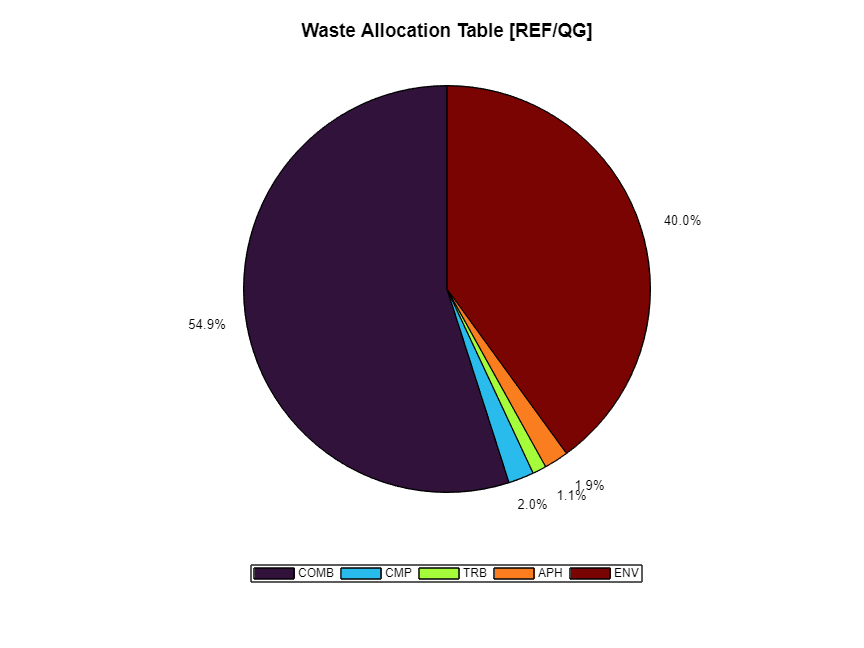

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

####  Show cost values and graphs for the study case (noIHE)

showResults(model,'ducost')


Process Unit Exergy Cost - REF

Key        kP*(J/J)    kin*(J/J)    kex*(J/J)     kF*(J/J)     kR*(J/J)       k(J/J)
—————————————————————————————————————————————————————————————————————————————————————
COMB         1.6173       1.5730       0.0443       1.3349       0.0184       1.1977
CMP          1.8341       1.7808       0.0533       1.6871       0.0024       1.0857
TRB          1.6871       1.6403       0.0468       1.6173       0.0006       1.0428
APH          1.7947       1.7426       0.0521       1.6173       0.0031       1.1078
HRSG         2.2014       2.1411       0.0603       1.6173       0.0000       1.3611
STCK         1.6173       1.5730       0.0443       1.6173       0.0000       1.0000



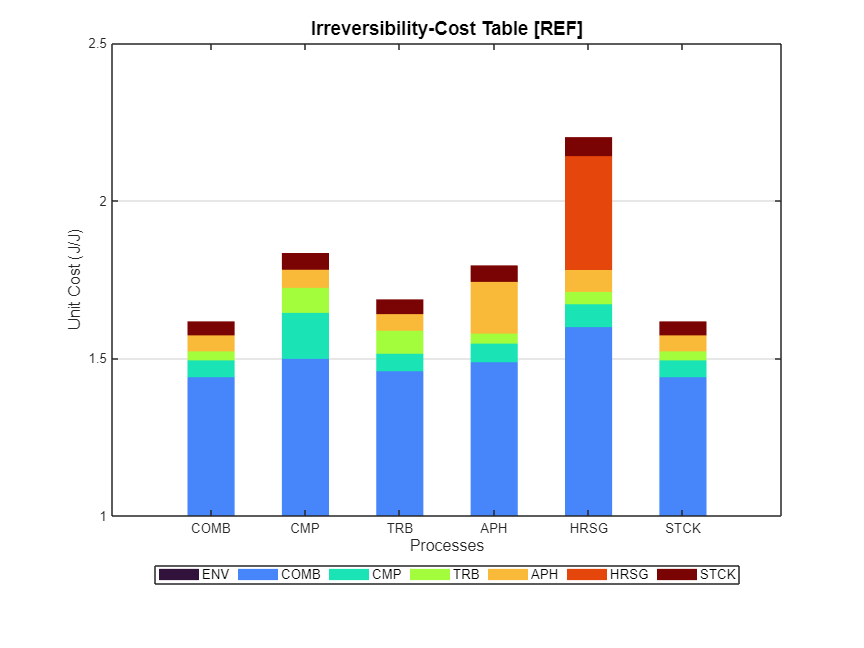

showGraph(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

Show the recycling analysis graph

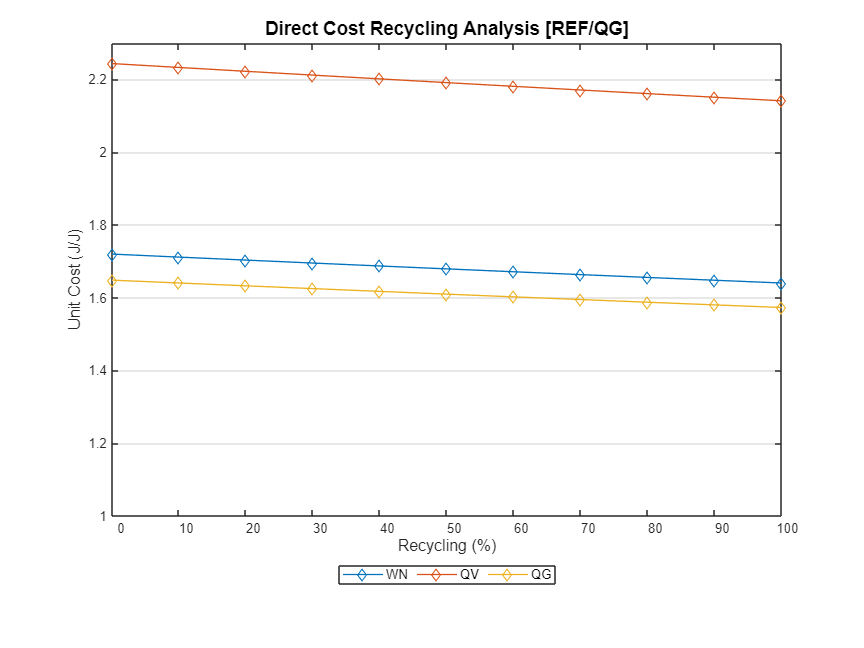

model.setRecycling(true);
showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);